% Pre-run Cleanup
clc
clear
close all
format long

currentFile = mfilename( 'fullpath' );
[pathstr,~,~] = fileparts( currentFile );
addpath( fullfile( pathstr, 'passive_CGW' ) );

% Set Dimensions
walkerDim.M = 1.0;          
walkerDim.m = 0.5;
walkerDim.I = 0.02;
walkerDim.l = 1.0;
walkerDim.c = 0.5;
walkerDim.g = 1.0;
walkerDim.gamma = 0.01;
walkerDim.movieFPS = 60;
steps = 20;

% Set Initial State
theta_1 = 0.19;
theta_2 = -2*theta_1;
omega_1 = -0.25;
omega_2 = 0.1;

q0 = [theta_1, omega_1, theta_2, omega_2];

%Root Finding
options = optimoptions('fsolve', 'Display', 'iter', 'TolFun', 1e-8);
[qstar, fval, exitflag] = fsolve(@(x) fixedpt(x,walkerDim), q0, options);


                                         Norm of      First-order   Trust-region
 Iteration  Func-count     f(x)          step         optimality    radius
     0          5       0.0143393                          1.15               1
     1         10     0.000407126      0.0672953          0.119               1
     2         15     7.36514e-06      0.0222296         0.0116               1
     3         20     1.14796e-08     0.00266353       0.000428               1
     4         25     4.07646e-14    0.000108857       8.04e-07               1
     5         30     1.22985e-24    2.04729e-07       4.42e-12               1

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 

exitflag

exitflag =      1


qstar

qstar =    0.162597832916598  -0.231869638198029  -0.325195665833211   0.037978466369517


fval

fval = 1.0e-12 *

   0.452804460593370  -0.365374397404139  -0.906719144211365   0.263011834533700


t0 = 0;
gamma_values = [0.007, 0.01, 0.015, 0.019];
q = cell(4,1);

parfor i = 1:4
    walkerDimTemp = walkerDim; % Create a temporary copy of walkerDim
    walkerDimTemp.gamma = gamma_values(i); % Modify the gamma field of the temporary structure
    [q{i}, ~] = multistep(t0,qstar,walkerDimTemp, steps); % Use the temporary structure in the function
end

q1 = q{1};
q2 = q{2};
q3 = q{3};
q4 = q{4};

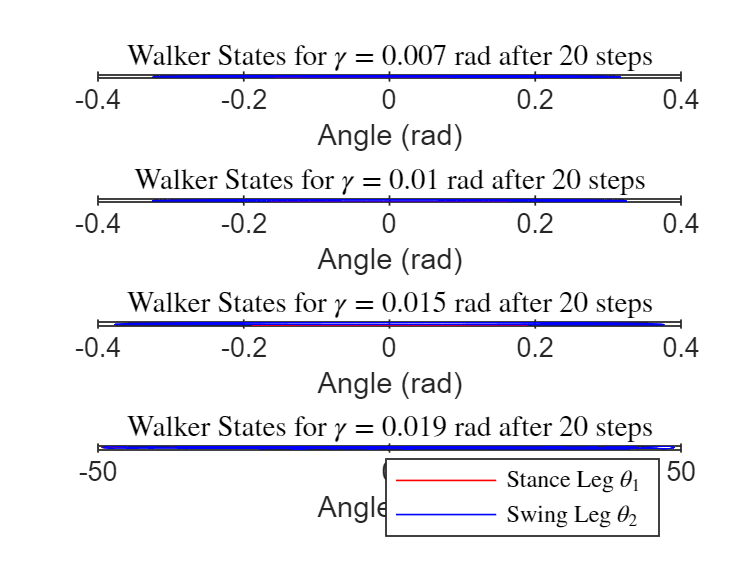

figure;
subplot(4,1,1);
plot(q1(:,1), q1(:,2), '-r', q1(:,3), q1(:,4), '-b');
title('Walker States for $\gamma$ = 0.007 rad after 20 steps', 'Interpreter', 'latex');
xlabel('Angle (rad)')
ylabel("Angular Velocity (rad/s)")

% Plot q2
subplot(4,1,2);
plot(q2(:,1), q2(:,2), '-r', q2(:,3), q2(:,4), '-b');
title('Walker States for $\gamma$ = 0.01 rad after 20 steps', 'Interpreter', 'latex');
xlabel('Angle (rad)')
ylabel("Angular Velocity (rad/s)")

% Plot q3
subplot(4,1,3);
plot(q3(:,1), q3(:,2), '-r', q3(:,3), q3(:,4), '-b');
title('Walker States for $\gamma$ = 0.015 rad after 20 steps', 'Interpreter', 'latex');
xlabel('Angle (rad)')
ylabel("Angular Velocity (rad/s)")

% Plot q4
subplot(4,1,4);
plot(q4(:,1), q4(:,2), '-r', q4(:,3), q4(:,4), '-b');
title('Walker States for $\gamma$ = 0.019 rad after 20 steps', 'Interpreter', 'latex');
xlabel('Angle (rad)')
ylabel("Angular Velocity (rad/s)")
legend("Stance Leg $\theta_1$", "Swing Leg $\theta_2$", 'Interpreter', 'latex')